# First part of the challenge

## Step 0

%% F1013B - Challenge - Diagnosis of malaria
clc;
close all; 
clear;


%% Step 0

v = 0.5; % Variable for the position in 3D space
dx = -1; % Variable to move the vertex
dy = 0;  % Variable to move the vertex
dz = 0;  % Variable to move the vertex
dx2 = 1;

largo = 3;  % length of the red plate de la lámina roja
largo2 = 3; % length of the blue plate
ancho = -0.2; 
alto = 1;

% Define vertices for rectangle 1 (red)
 vertices = [-v*ancho+dx  -v*largo+dy  -v+dz;  %v1
             -v*ancho+dx   v*largo+dy  -v+dz;  %v2
              v*ancho+dx   v*largo+dy  -v+dz;  %v3 
              v*ancho+dx  -v*largo+dy  -v+dz;  %v4
             -v*ancho+dx  -v*largo+dy   v+dz;  %v5
             -v*ancho+dx   v*largo+dy   v+dz;  %v6
              v*ancho+dx   v*largo+dy   v+dz;  %v7
              v*ancho+dx  -v*largo+dy   v+dz]; %v8
 
% Define the polygon (patch) usando the vertices previously defined
caras = [  % complete code
    1 2 3 4; % Bottom face
    5 6 7 8; % Top face
    1 2 6 5; % Front face
    3 4 8 7; % Back face
    1 4 8 5; % Left face
    2 3 7 6; % Right face
 ];
 
% Define vertices for rectangle 2 (blue)
vertices2 = [-v*ancho+dx2  -v*largo+dy  -v+dz;  %v1
             -v*ancho+dx2   v*largo+dy  -v+dz;  %v2
              v*ancho+dx2   v*largo+dy  -v+dz;  %v3 
              v*ancho+dx2  -v*largo+dy  -v+dz;  %v4
             -v*ancho+dx2  -v*largo+dy   v+dz;  %v5
             -v*ancho+dx2   v*largo+dy   v+dz;  %v6
              v*ancho+dx2   v*largo+dy   v+dz;  %v7
              v*ancho+dx2  -v*largo+dy   v+dz]; %v8
         
% Define the polygon (patch) usando the vertices previously defined
caras2 = [  % complete code
    1 2 3 4; % Bottom face
    5 6 7 8; % Top face
    1 2 6 5; % Front face
    3 4 8 7; % Back face
    1 4 8 5; % Left face
    2 3 7 6; % Right face
 ];   

% Specify the polygons using patch
hold on;
patch('Vertices', vertices, 'Faces', caras, 'FaceColor', 'r', 'EdgeColor', 'k'); % Red plate
patch('Vertices', vertices2, 'Faces', caras2, 'FaceColor', 'b', 'EdgeColor', 'k'); % Blue plate

axis([-2 2 -2 2 -2 2]); % scale axes
view(30,30); % view the angle


## Step 1


%% Step 1
% The goal of this section is to simply plot a meshgrid around the parallel
% plates, in such a way that includes the interior and exterior of them
% Hint: use the functions mesh grid and plot

% create the mesh
x0 = -2;
x1 = 2;
y0 = -2;
y1 = 2;  
nx = 0.3;
ny = 0.3;
       
[xGrid, yGrid] = meshgrid(x0:nx:x1, y0:ny:y1); % mesh parametrization % complete code here
zGrid = xGrid * 0; % for completenes we create a parameter for z, but we make it zero

% plot
plot(xGrid,yGrid,'.b');


## Step 2

%% Step 2: Add a vector field and plot
% Hint: use the function quiver3
% complete code here
h = quiver3(xGrid, yGrid, zGrid, xGrid, yGrid, zGrid, 'g');

hold on;


# Second part of the challenge

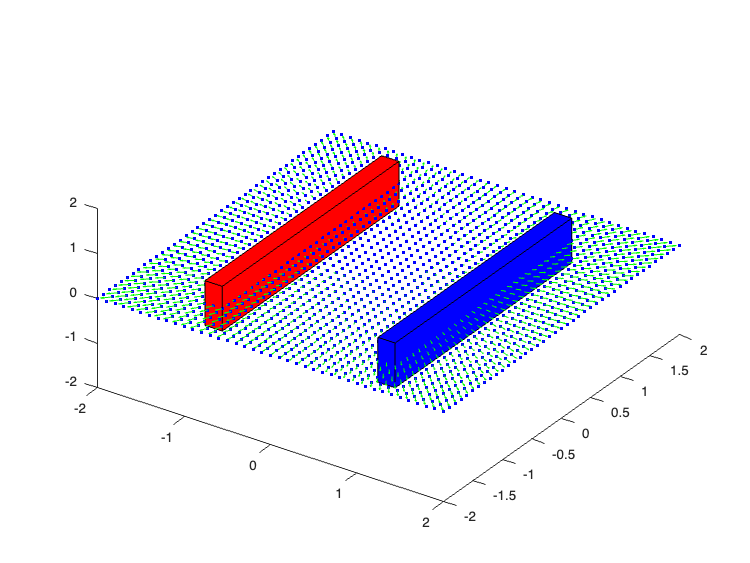

% First red-raw the plates and comment the lines (like above)
clc; 
clear;
close all;

v = 0.5; % 

dx = -1; % 
dx2 = 1;
dy = 0;  % 
dz = 0;  % 

largo = 3;  % 
largo2 = 3; % 
ancho = -0.2;
alto = 1;

% Define vertices for rectangle 1 (red)
vertices = [-v*ancho+dx  -v*largo+dy  -v+dz;  %v1
             -v*ancho+dx   v*largo+dy  -v+dz;  %v2
              v*ancho+dx   v*largo+dy  -v+dz;  %v3 
              v*ancho+dx  -v*largo+dy  -v+dz;  %v4
             -v*ancho+dx  -v*largo+dy   v+dz;  %v5
             -v*ancho+dx   v*largo+dy   v+dz;  %v6
              v*ancho+dx   v*largo+dy   v+dz;  %v7
              v*ancho+dx  -v*largo+dy   v+dz]; %v8
 
% Define the polygon (patch) usando the vertices previously defined 
caras = [  % complete code
    1 2 3 4; % Bottom face
    5 6 7 8; % Top face
    1 2 6 5; % Front face
    3 4 8 7; % Back face
    1 4 8 5; % Left face
    2 3 7 6; % Right face
];
 
% Define vertices for rectangle 2 (blue)
vertices2 = [-v*ancho+dx2  -v*largo+dy  -v+dz;  %v1
             -v*ancho+dx2   v*largo+dy  -v+dz;  %v2
              v*ancho+dx2   v*largo+dy  -v+dz;  %v3 
              v*ancho+dx2  -v*largo+dy  -v+dz;  %v4
             -v*ancho+dx2  -v*largo+dy   v+dz;  %v5
             -v*ancho+dx2   v*largo+dy   v+dz;  %v6
              v*ancho+dx2   v*largo+dy   v+dz;  %v7
              v*ancho+dx2  -v*largo+dy   v+dz]; %v8
         
% Define the polygon (patch) usando the vertices previously defined
caras2 = [  % complete code
    1 2 3 4; % Bottom face
    5 6 7 8; % Top face
    1 2 6 5; % Front face
    3 4 8 7; % Back face
    1 4 8 5; % Left face
    2 3 7 6; % Right face
];     

% plot
% Specify the polygons using patch
hold on;
patch('Vertices', vertices, 'Faces', caras, 'FaceColor', 'r', 'EdgeColor', 'k'); % Red plate
patch('Vertices', vertices2, 'Faces', caras2, 'FaceColor', 'b', 'EdgeColor', 'k'); % Blue plate


axis([-2 2 -2 2 -2 2]); % 
view(30,30); % 


%@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@
%@@@@@@  Principle of superposition                               @@@@@@
%@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@@

% mesh creation
x0 = -2;
x1 = 2;
y0 = -2;
y1 = 2;  
nx = 0.1; % make resolution finer to ease the visualization
ny = 0.1;
       
[xGrid, yGrid] = meshgrid(x0:nx:x1, y0:ny:y1); % mesh parametrization % complete code here
zGrid = xGrid * 0; % for completenes we create a parameter for z, but we make it zero


% plot grid
plot(xGrid,yGrid,'.b');
h = quiver3(xGrid, yGrid, zGrid, xGrid, yGrid, zGrid, 'g');

hold on;

## **Now charges will appear!**

**First charge**

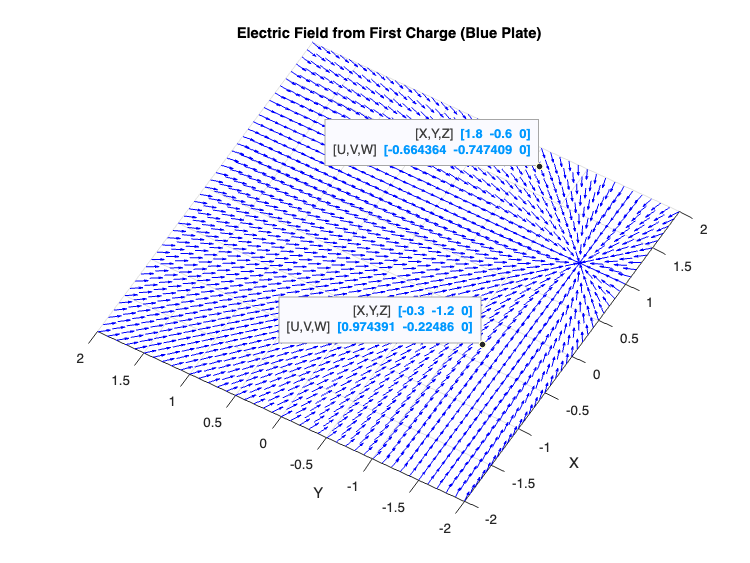


% Negative 1 (blue plate)
Qn1 = -20; % Negative charge on the blue surface
eps0 = 8.854e-12;  % Dielectric constant of the media
k = 1/(4*pi*eps0); % Electric constant
Rxn1 = xGrid - (1); % % Distance in x from charge
Ryn1 = yGrid - (-largo2/2); % % Distance in y from charge
Rzn1 = zGrid;% - 0.5;     % Distance in z from charge

% Calculation of the field from a single charge 
% E = k * (qr / r^3)
% R = distance between the charges

R = sqrt(xGrid.^2 + yGrid.^2 + zGrid.^2);
Ex = k * Qn1 .* Rxn1 ./ R.^3;
Ey = k * Qn1 .* Ryn1 ./ R.^3;
Ez = k * Qn1 .* Rzn1 ./ R.^3;
E = sqrt(Ex.^2 + Ey.^2 + Ez.^2); % Magnitude of the field


% normalize the vector components by dividing by E
i = Ex ./ E; 
j = Ey ./ E;
k = Ez ./ E; 

% plot [Hint: use quiver3 as the previous stage]
figure;
quiver3(xGrid, yGrid, zGrid, i, j, k, 'b'); % Green arrows for field

% Final visualization settings
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Electric Field from First Charge (Blue Plate)');
grid on;
hold off;

**Second charge (when adding the field remember the superposition principle!!!!)**

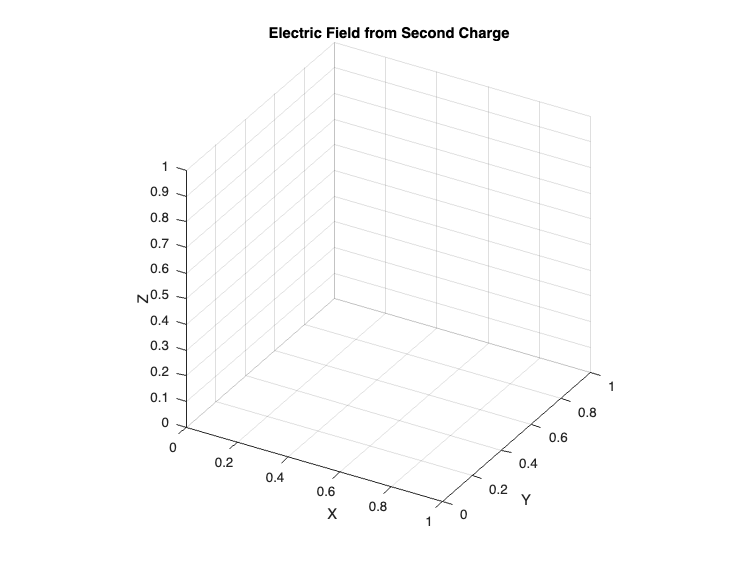

% Postive charge 1 (red plate)
Qp1 = 20; 
Rxp1 = xGrid - (-1); % COMMENT THIS LINE
Ryp1 = yGrid - (-1.5); % COMMENT THIS LINE
Rzp1 = zGrid; % COMMENT THIS LINE

% Calculation of the field from a single charge 
% E = k * (qr / r^3)
% R = distance between the charges

R = sqrt(xGrid.^2 + yGrid.^2 + zGrid.^2);
Ex = k * Qn1 .* Rxn1 ./ R.^3;
Ey = k * Qn1 .* Ryn1 ./ R.^3;
Ez = k * Qn1 .* Rzn1 ./ R.^3;

% Aplicamos el **Principio de Superposición** sumando campos:
Ex_total = Ex + Ex;
Ey_total = Ey + Ey;
Ez_total = Ez + Ez;
E = sqrt(Ex_total.^2 + Ey_total.^2 + Ez_total.^2); 

% normalize the vector components by dividing by E
i = Ex_total ./ E; 
j = Ey_total ./ E;
k = Ez_total ./ E; 

% plot [Hint: use quiver3 as the previous stage]
figure;
quiver3(xGrid, yGrid, zGrid, i, j, k, 'g'); 

% Configuración de la visualización
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Electric Field from Second Charge');
grid on;
axis equal;
view(30, 30);

**Third charge (when adding the field remember the superposition principle!!!!!!!!!!!!!!!!!!)**

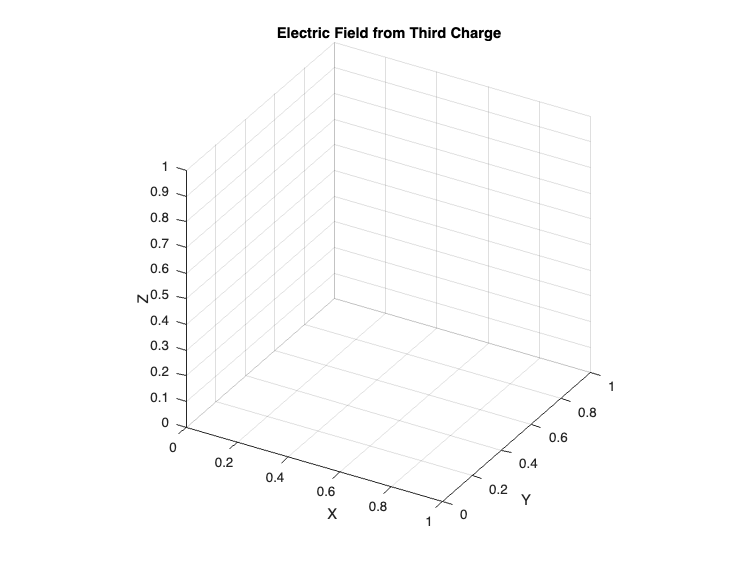

% NEGATIVE 2
Qn2 = -20; % Negative Charge
Rxn2 = xGrid - (1); % Distance in x from the charge
Ryn2 = yGrid - (largo2/2); % Distance in y from the charge
Rzn2 = zGrid - 0.5; % Distance in z from charge


%E = k * (qr / r^3)
%R = distance between the charges

R = sqrt(Rxn2.^2 + Ryn2.^2 + Rzn2.^2);
Ex = k * Qn2 .* Rxn2 ./ R.^3;
Ey = k * Qn2 .* Ryn2 ./ R.^3;
Ez = k * Qn2 .* Rzn2 ./ R.^3;
E = sqrt(Ex.^2 + Ey.^2 + Ez.^2); 

% normalize the vector components by dividing by E
i = Ex ./ E; 
j = Ey ./ E;
k = Ez ./ E; 

% plot [Hint: use quiver3 as the previous stage]
figure;
quiver3(xGrid, yGrid, zGrid, i, j, k, 'r');

xlabel('X'); ylabel('Y'); zlabel('Z');
title('Electric Field from Third Charge');
grid on;
axis equal;
view(30, 30);

**Fourth charge (when adding the field remember the superposition principle!!!!!!!!!!!!!!!!!!)**

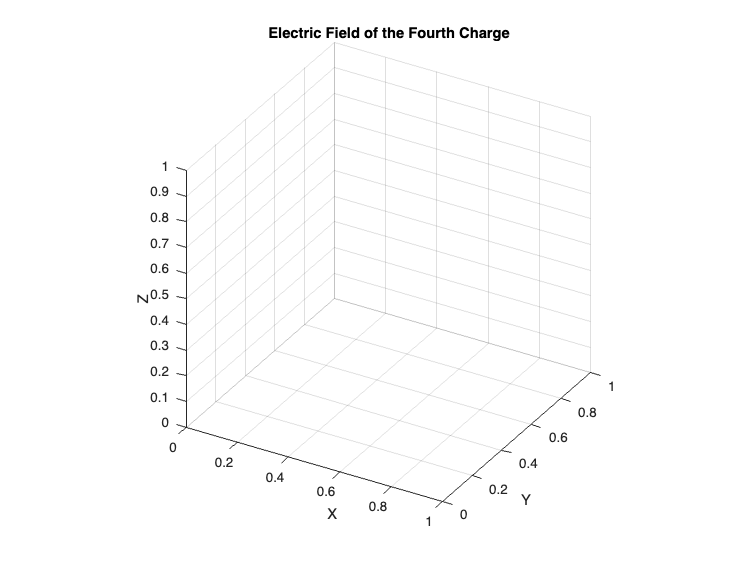

%POSITIVA 2
Qp2 = 20; % Positive charge
Rxp2 = xGrid - (-1); % Distance in x from charge
Ryp2 = yGrid - (1.5); % Distance in y from charge
Rzp2 = zGrid - 0.5; % Distance in z from charge


R = sqrt(Rxp2.^2 + Ryp2.^2 + Rzp2.^2);
Ex = k * Qp2 .* Rxp2 ./ R.^3;
Ey = k * Qp2 .* Ryp2 ./ R.^3;
Ez = k * Qp2 .* Rzp2 ./ R.^3;
E = sqrt(Ex.^2 + Ey.^2 + Ez.^2);


% normalize the vector components by dividing by E
i = Ex ./ E; 
j = Ey ./ E;
k = Ez ./ E; 

% plot [Hint: use quiver3 as the previous stage]
% This should be the complete plot
figure;
quiver3(xGrid, yGrid, zGrid, i, j, k, 'r'); % Red arrows for the field

xlabel('X'); ylabel('Y'); zlabel('Z');
title('Electric Field of the Fourth Charge');
grid on;
axis equal;
view(30, 30);